p2f = 'C:\Data\tuning\2016-07-09_11-13-28\';
files = dir([p2f,'LFP_data_chan*_stimlocked.mat']);

dat = cell(1,length(files));

for it = 1:length(files)
    
    [dat{it}] =load([p2f,files(it).name]);
    
end;

[chanID] = makeCSClabels();
n = length(chanID)/8;

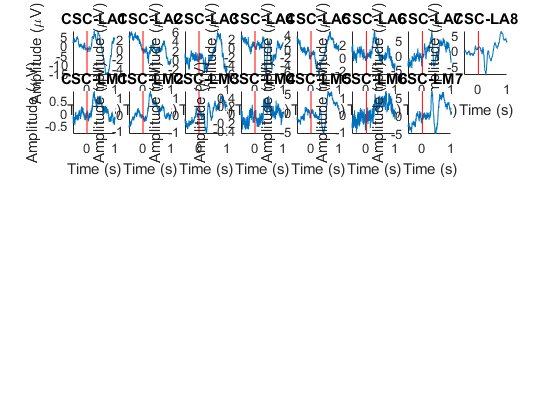

figure(1);
c = 0;
for it = 1:length(dat)
    c = c+1;
    subplot(n,8,c);
    hold on;
    plot(dat{it}.tlck.time,dat{it}.tlck.avg);
    plot([0 0],[min(dat{it}.tlck.avg) max(dat{it}.tlck.avg)],'r');
    
    axis tight;
    xlim([-.5 1]);
    xlabel('Time (s)');
    ylabel('Amplitude (\muV)');
    title([chanID(it)]);
end;
set(gcf,'Color','w');

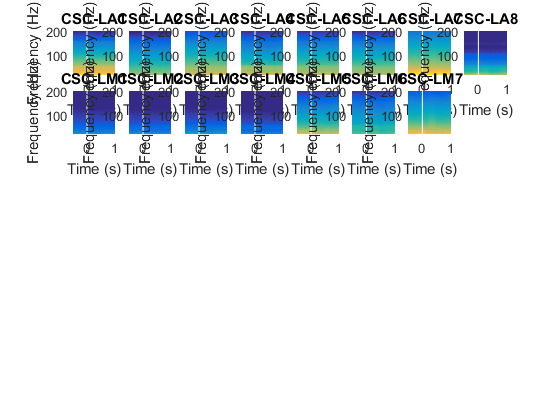

figure(2);
c = 0;
for it = 1:length(dat)
    c = c+1;
    subplot(n,8,c);
    hold on;
    imagesc(dat{it}.powH.time,dat{it}.powH.freq,squeeze(20*log10(mean(dat{it}.powH.powspctrm,1))));
    axis xy;
    if it ==1
        ca =caxis;
    else
        caxis(ca);
    end;
    plot([0 0],[min(dat{it}.powH.freq) max(dat{it}.powH.freq)],'w');
    axis tight;
    xlim([-.5 1]);
    
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title([chanID(it)]);
end;
set(gcf,'Color','w');

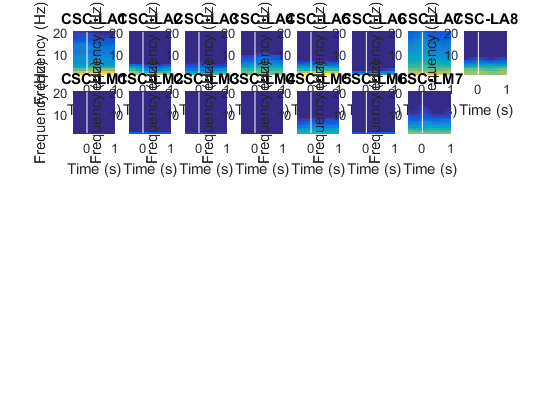

figure(3);
c = 0;
for it = 1:length(dat)
    c = c+1;
    subplot(n,8,c);
    hold on;
    imagesc(dat{it}.powL.time,dat{it}.powL.freq,squeeze(20*log10(mean(dat{it}.powL.powspctrm,1))));
    axis xy;
    if it ==1
        ca =caxis;
    else
        caxis(ca);
    end;
    plot([0 0],[min(dat{it}.powL.freq) max(dat{it}.powL.freq)],'w');
    axis tight;
    xlim([-.5 1]);
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title([chanID(it)]);
end;
set(gcf,'Color','w');